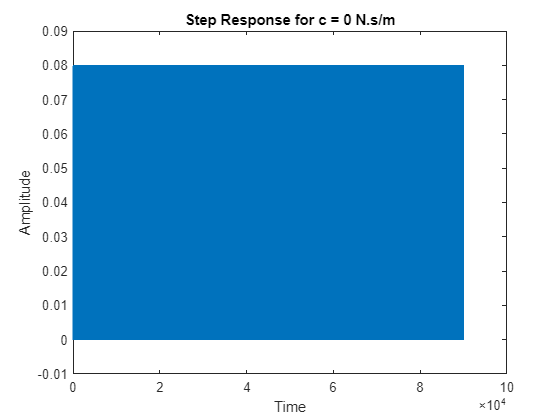

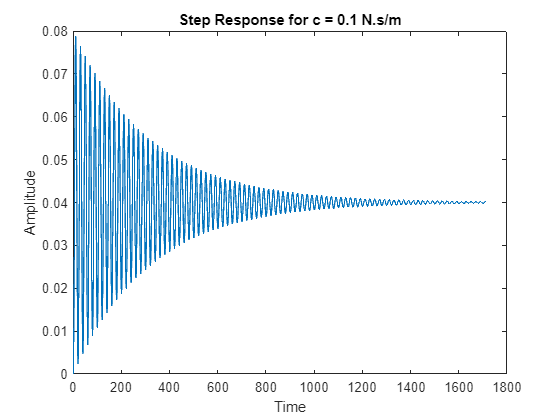

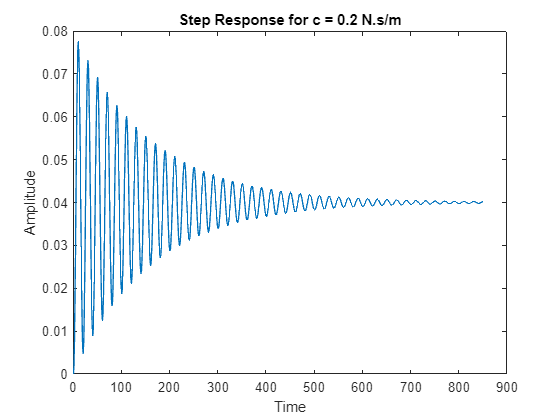

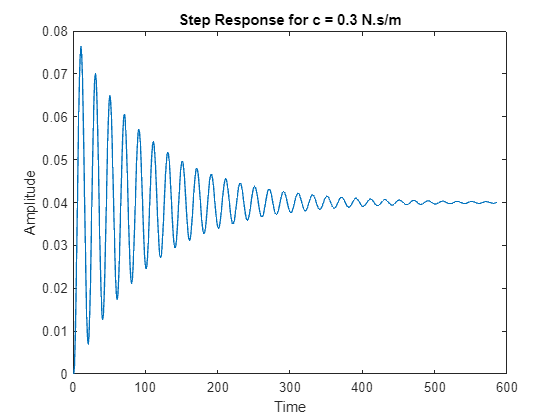

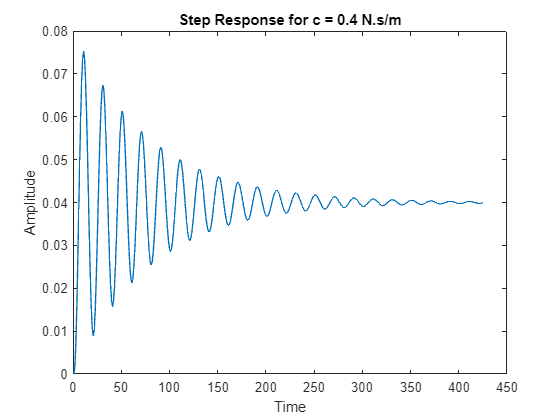

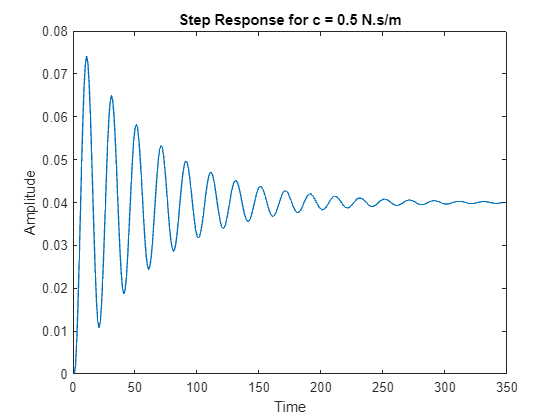

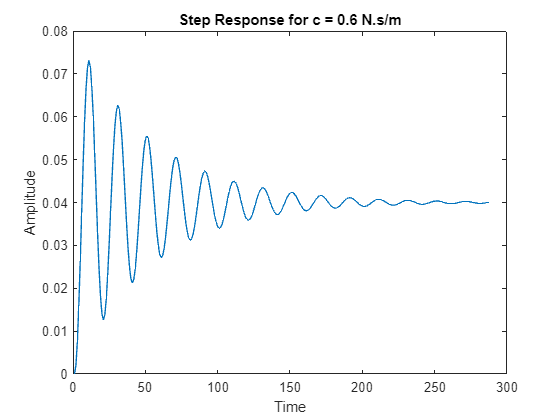

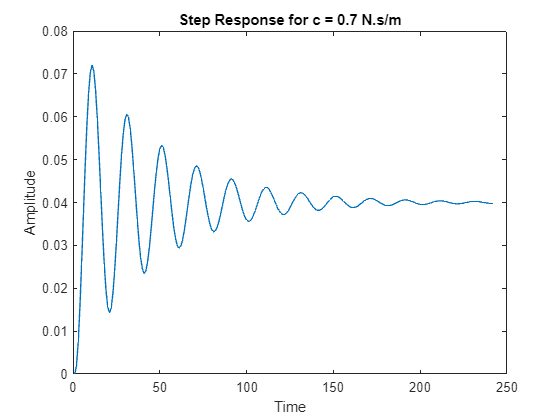

% A1.1
% Mass-Damper Spring System

m = 1;                % Mass
c_values = 0:0.1:20;  % Varying Damping Constant from 0 to 20
k = 25;               % Spring constant

% Loop through different values of c
for i = 1:length(c_values)
    c = c_values(i);

    % Transfer Function
    num = 1;
    den = [m, c, k];
    sys = tf(num, den);

    % Calculate Step Response
    step_response = step(sys);
    
    % Plot Step Response
    figure; 
    plot(step_response)
    
    % Labels and Title
    xlabel('Time')
    ylabel('Amplitude')
    title(['Step Response for c = ' num2str(c) ' N.s/m'])
end


% Calculate smallest value of c that prevents oscillation
for i = 1:length(c_values)
    c = c_values(i);
    sys = tf(1, [m, c, k]);
    poles = pole(sys);
    
    % Check for System stability (no complex poles)
    if all(real(poles) < 0)
        smallest_c = c;
        break;
    end
end

fprintf('The smallest value of c that prevents oscillation is %0.1f N.s/m ', smallest_c);

The smallest value of c that prevents oscillation is 0.1 N.s/m 

% A1.2
% Mass-Damper Spring System

L = 1;      % Inductance
C = 400e-6; % Capacitance

% Resistance values
R_values = [125, 100, 30];

% Transfer Function
for i = 1:length(R_values)
    R = R_values(i);
    
    num = 1/(L*C);           % Numerator
    den = [1, R/L, 1/(L*C)]; % Denominator

    sys(i) = tf(num, den)  % Create Transfer Function
    sys(i).UserData.R = R;  % Store Resistance in user data
end

sys =
 
  From input 1 to output:
         2500
  ------------------
  s^2 + 125 s + 2500
 
  From input 2 to output:
         2500
  ------------------
  s^2 + 100 s + 2500
 
  From input 3 to output:
        2500
  -----------------
  s^2 + 30 s + 2500
 
Continuous-time transfer function.
Model Properties

sys =
 
  From input 1 to output:
         2500
  ----


% Step Input Responses, Pole Positions, and Ramp Responses using ltiview
for i = 1:length(R_values)

    fprintf('Step Input Response for R = %d:\n', i);
    ltiview(sys(i))
    
    fprintf('Pole Positions for R = %d:\n', i);
    pole(sys(i))

    fprintf('Ramp Response for R = %d:\n', i);
    time = linspace(0, 0.01, 5);
    alpha = 1;
    ramp = alpha * time;
    lsim(sys(i), ramp, time)

end

Step Input Response for R = 1:


Pole Positions for R = 1:


ans =   -100
   -25


Ramp Response for R = 1:


Step Input Response for R = 2:


Pole Positions for R = 2:


ans =   -50.0000
  -50.0000


Ramp Response for R = 2:


Step Input Response for R = 3:


Pole Positions for R = 3:


ans =  -15.0000 +47.6970i
 -15.0000 -47.6970i


Ramp Response for R = 3:



ltiview(sys(1),sys(2), sys(3))

pole(sys)

ans = 1.0e+02 *

  -1.0000 + 0.0000i
  -0.2500 + 0.0000i
  -0.5000 + 0.0000i
  -0.5000 + 0.0000i
  -0.1500 + 0.4770i
  -0.1500 - 0.4770i


lsim(sys(1), sys(2), sys(3), ramp, time)
ylim([0, 0.001])

% Resistor Value and Damping Time

% Range of Resistance
R_values = linspace(0.1, 10, 100);  % Adjust the Range
shortest_settling_time = Inf;       % Initialize to a large value

for i = 1:length(R_values)
    R = R_values(i);

    num = 1 / (L * C);
    den = [1, R / L, 1 / (L * C)];

    % Transfer Function
    sys = tf(num, den);

    % Step Response
    [time, response] = step(sys);

    % Find the Settling Time
    [settling_time, index] = max(time(response >= 0.98 * max(response)));

    % Check if the current settling time is the shortest
    if settling_time < shortest_settling_time
        shortest_settling_time = settling_time;
        best_R = R;
        best_damping_ratio = abs(real(pole(sys(1))));
    end
end

fprintf('Best Resistance: %.4f\n', best_R);

Best Resistor Value: 9.2000


fprintf('Corresponding Damping Ratio: %.4f\n', best_damping_ratio);

Corresponding Damping Ratio: 4.6000
Corresponding Damping Ratio: 4.6000


fprintf('Shortest Settling Time: %.4f seconds\n', shortest_settling_time);

Shortest Settling Time: 0.9970 seconds
